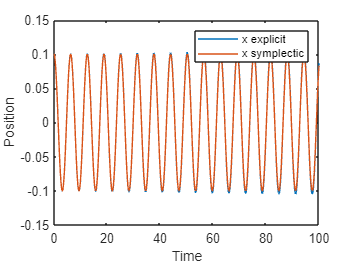

end_time=100;
dt=0.001;
pts=(end_time/dt)+1;
%Planar pendulum system
t=linspace(0,end_time,pts);
x0=[0.1 0];
x=zeros([101,2]);
x(1,:)=x0;
dt=t(2)-t(1);
for i=1:length(t)-1
    x_dot=x(i,2);
    x_ddot=-sin(x(i,1));
    x(i+1,2)=x(i,2)+x_ddot*dt;
    x(i+1,1)=x(i,1)+x_dot*dt;
end
x_explicit=x;
x=zeros([101,2]);
x(1,:)=x0;
%Implicit Euler
for i=1:length(t)-1
    x_dot=x(i,2);
    x_ddot=-sin(x(i,1));
    for j=1:10
    x(i+1,2)=x(i,2)+x_ddot*dt;
    x(i+1,1)=x(i,1)+x_dot*dt;
    x_dot=x(i+1,2);
    x_ddot=-sin(x(i+1,1));
    end
end
x_implicit=x;
x=zeros([101,2]);
x(1,:)=x0;
%Semi-implicit Euler emthod
for i=1:length(t)-1
    x_ddot=-sin(x(i,1));
    x(i+1,2)=x(i,2)+dt*x_ddot;
    x_dot=x(i+1,2);
    x(i+1,1)=x(i,1)+dt*x_dot;
end
x_symplectic=x;
%Using ode45
[T,X]=ode45(@rates,[t(1) t(length(t))],x0);
plot(t,x_explicit(:,1));
xlabel('Time');
ylabel('Position');
hold on;
plot(t,x(:,1));
legend('x explicit','x symplectic');
hold off;

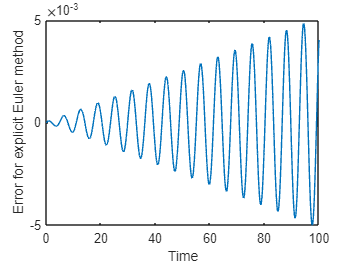

plot(t,x_explicit(:,1)-x(:,1));
xlabel('Time');
ylabel('Error for explicit Euler method');

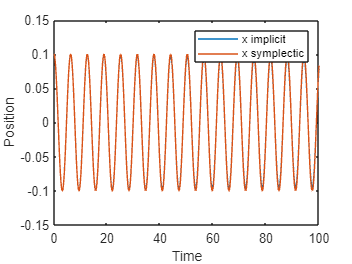



plot(t,x_implicit(:,1));
xlabel('Time');
ylabel('Position');
hold on;
plot(t,x(:,1));
legend('x implicit','x symplectic');
hold off;

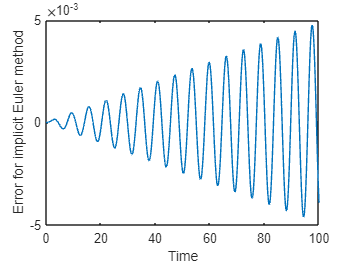

plot(t,x_implicit(:,1)-x(:,1));
xlabel('Time');
ylabel('Error for implicit Euler method');

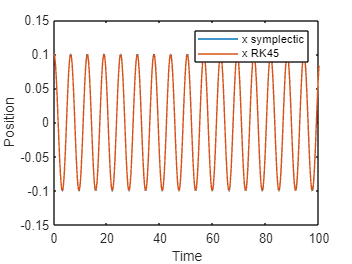



plot(t,x_symplectic(:,1));
xlabel('Time');
ylabel('Position');
hold on;
plot(T,X(:,1));
legend('x symplectic','x RK45');
hold off;

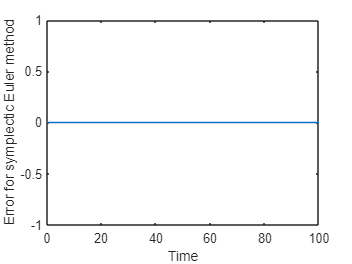

plot(t,x_symplectic(:,1)-x(:,1));
xlabel('Time');
ylabel('Error for symplectic Euler method');

function x_dash=rates(t,x)
    x_dash=[0;0];
    x_dash(1)=x(2);
    x_dash(2)=-sin(x(1));
end

function theta1=angle(theta)
    theta2=cast(theta/(pi),'int8');
    theta1=theta-theta2*pi;
end